clear; close; clc;
% note for ardupilot data see
% https://ardupilot.org/plane/docs/logmessages.html\load('StateMPCLongDataSweep.mat')

% our aircraft Data
% load('StateMPCLongDataSweep.mat')
% load('ControlMPCLongDataSweep.mat')

% with one matrix
%load('FlightData.mat');
load('FlightDataUncontrolled.mat')
State = StateAndControl(1:5,:);
Control = StateAndControl(6,:);
% beaver model

%load('ALong.mat')

dt = 1

dt = 1

stateData = State

stateData =          0    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0006    0.0010    0.0014    0.0018    0.0028    0.0038    0.0048    0.0059    0.0069    0.0085    0.0100    0.0116    0.0131    0.0147    0.0171    0.0196    0.0220    0.0245    0.0269    0.0307    0.0345    0.0383    0.0421    0.0459    0.0534    0.0609    0.0684    0.0759    0.0833    0.1061    0.1289    0.1517    0.1745    0.1973    0.2368    0.2763    0.3158    0.3553    0.3948    0.4536    0.5124
  300.0000  300.0000  299.9999  299.9998  299.9997  299.9991  299.9985  299.9979  299.9973  299.9928  299.9880  299.9830  299.9778  299.9628  299.9466  299.9294  299.9115  299.8928  299.8636  299.8334  299.8026  299.7712  299.7395  299.6890  299.6382  299.5873  299.5365  299.4858  299.4078  299.3304  299.2537  299.1777  299.1023  298.9554  298.8108  298.6685  298.5281  298.3897  297.9780  297.5784  297.1874  296.8025  296.4215  295.7658  295.1094  294.4470  293.7751  293.0911  292.0

controlData = Control

controlData =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Truncate = true

Truncate = logical
   1


## Create Snapshot Matrices

X = stateData(:,1:end-1);
Xprime = stateData(:,2:end);
Upsilon = controlData(:,1:end-1);

Omega = [X; Upsilon];


## Singular Value Decomposition of the inputs

[U,Sigma,V] = svd(Omega,"econ");

if Truncate == true % should we truncate?
    truncationThreshold = 1e-5;%1e-10;
    rTilde = length(find(diag(Sigma) > truncationThreshold));
    % rTilde = sum(diag(Sigma)>threshold); % may be faster?
else
    rTilde = length(diag(Sigma));
end

UTilde = U(:,1:rTilde);
SigmaTilde = Sigma(1:rTilde ,1:rTilde);
VTilde = V(:,1:rTilde);


## Singular Value Decomposition on the state output

[U,Sigma,V] = svd(Xprime,"econ");

if Truncate == true% should we truncate?
    truncationThreshold = 1e-5;%1e-10;
    r = length(find(diag(Sigma) > truncationThreshold));
    % rTilde = sum(diag(Sigma)>threshold); % may be faster?
else
    r = length(diag(Sigma));
end

UHat = U(:,1:r);
SigmaHat= Sigma(1:r,1:r);
VHat = V(:,1:r);


## Compute the (reduced) aproximate system advancing operators

n = size(X,1);
q = size(Upsilon,1);
UTilde1 = UTilde(1:n,:);
%UTilde2 = UTilde(n+q:end,:); % this differs form the implementation in the book i belvieve that the book has an error
UTilde2 = UTilde(n+q:n+q,:); % this is what the book had

ATilde = UHat' * Xprime * VTilde * inv(SigmaTilde) * UTilde1' * UHat;
BTilde = UHat' * Xprime * VTilde * inv(SigmaTilde) * UTilde2';

## Eigen Decomposition of (reduced) state advancing operator

[W,Lambda] = eig(ATilde);

## Dynamic Modes of System State

Phi = Xprime * VTilde * inv(SigmaTilde) * UTilde1' * UHat * W;
contTimeEigVals = log(diag(Lambda))/dt

contTimeEigVals =   -0.0147 + 0.1944i
  -0.0147 - 0.1944i
   0.0070 + 0.0000i
  -0.0240 + 0.0313i
  -0.0240 - 0.0313i


%plot(contTimeEigVals,"xr");

## compare results

%load('ALong.mat')
Along = [-0.0374,17.4632,0,-32.0236; -0.340,-170.4133,185.0700,-3.3658;0,-5.5002,-2.1809,0;0,0,1.0000,0];
[W,Lambda] = eigs(Along);
diag(Lambda)

ans = 1.0e+02 *

  -1.6409 + 0.0000i
  -0.0851 + 0.0000i
  -0.0001 + 0.0021i
  -0.0001 - 0.0021i


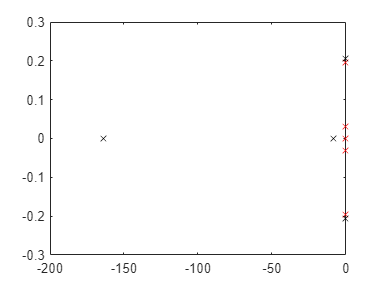

plot(contTimeEigVals,"xr"); hold on
plot(diag(Lambda),'xk');